## Signal Generation

fs = 10000000;
dt = 0.000007;
aquisition_time = 10*dt; % guess
nr_samples = round(fs*aquisition_time);
aquisition_time = nr_samples./fs; % actual
t = linspace(0,aquisition_time,nr_samples);

wave_type = "Square";
wave_f = 25000;
wave_vpp = 1;
wave_amp = wave_vpp/2;

if wave_type == "Sinusoidal"
    y_orig = sin(wave_f.*2.*pi.*t);
elseif wave_type == "Square"
    y_orig = wavesquare(wave_f,t);
elseif wave_type == "Triangle"
    y_orig = wavetriangle(wave_f,t);
end

wave_noise_max_amp = 0.1;
has_noise = true;

y_orig = wave_amp.*y_orig;
y = y_orig;

if has_noise && 1 == 1 % removes unreach warning
    y = y + (wave_noise_max_amp*rand(1,nr_samples) - ...
        wave_noise_max_amp/2);  
end

fprintf("Samples: %u\n" + ...
    "Aquisition Time: %1.3f seconds\n",...
    nr_samples,aquisition_time);

Samples: 700
Aquisition Time: 0.000 seconds


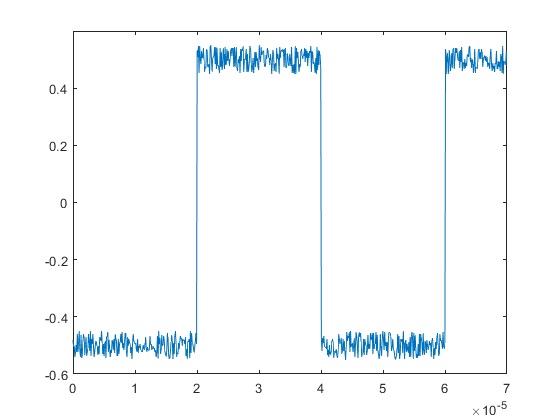


plot(t,y)
axis([0 t(end) -wave_amp*1.2 wave_amp*1.2])

## Aquisition Type

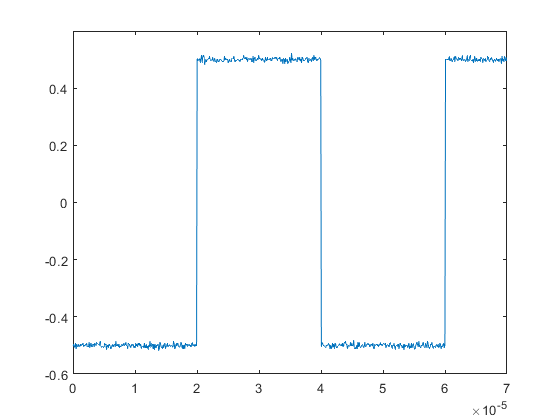

aquisition_type = "Avarage";
if aquisition_type == "Avarage"
    nr_avg = 21;
    y_samples = zeros(length(y),nr_avg);
    for i = 1:nr_avg
        y_temp = y_orig';
        if has_noise && 1 == 1 % removes unreach warning
            y_temp = y_temp + (wave_noise_max_amp*rand(nr_samples,1) - ...
            wave_noise_max_amp/2);  
        end
        y_samples(:,i) = y_temp;
    end
    y = sum(y_samples,2)'./nr_avg;
end

plot(t,y)
axis([0 t(end) -wave_amp*1.2 wave_amp*1.2])

## Output

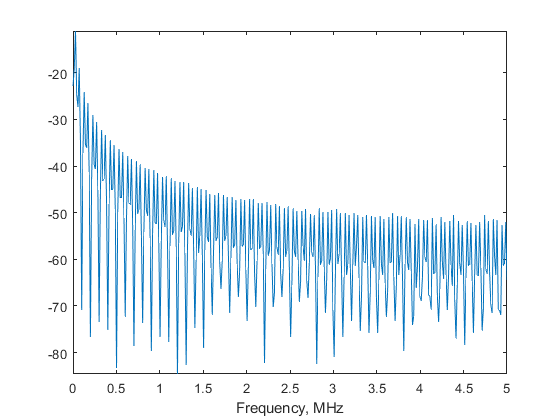

[Y,f] = fft2NdB(y,fs);
if false&& 1 == 1
    flower = 0; fupper = 2500000;
else
    flower = f(1); fupper = f(end);
end

if fupper >= 1000000
    fplot_divisor = 1000000;
    funit = "M";
elseif fupper >= 1000
    fplot_divisor = 1000;
    funit = "k";
else
    fplot_divisor = 1;
    funit = "";
end

plot(f/fplot_divisor,Y);
axis([flower/fplot_divisor fupper/fplot_divisor min(Y) max(Y)])
xlabel(sprintf("Frequency, %sHz",funit));